%% group_all_patiedgecolornts.m
% Loop over Patient2–Patient12, compute per-patient condition-level means
% (pre/post, Work & Modulus) using compute_patient_prepost.m,
% then average across patients, run paired t-tests, and plot:
%   - Grouped bar (Pre vs Post)
%   - Patient dots
%   - Significance brackets + asterisks where p<0.05

clear; clc;

%% 1. Root directory containing Patient2 ... Patient12
rootDir = 'C:\Users\Admin\Desktop\ManoView Data Analysis';

% Get all patient folders: 'Patient2', 'Patient3', ...
patientDirs = dir(fullfile(rootDir, 'Patient*'));

% Map: key = 'condNN' (NN = condition number), value = struct with fields:
%   condNum   : numeric index (1,2,3,...)
%   pretty    : first label string we see (for x-axis)
%   preWork   : [nPatients x 1] Work pre
%   postWork  : [nPatients x 1] Work post
%   preMod    : [nPatients x 1] Modulus pre
%   postMod   : [nPatients x 1] Modulus post
condStats = containers.Map('KeyType','char','ValueType','any');

%% 2. Loop over patients
for p = 1:numel(patientDirs)
    if ~patientDirs(p).isdir, continue; end

    patientName = patientDirs(p).name;

    % Restrict to Patient2–Patient12
    tok = regexp(patientName, '^Patient(\d+)$', 'tokens', 'once');
    if isempty(tok), continue; end
    pid = str2double(tok{1});
    if pid < 2 || pid > 12, continue; end

    patientPath = fullfile(rootDir, patientName);
    fprintf('=== Processing %s ===\n', patientName);

    % ---- Per-patient analysis ----
    R = compute_patient_prepost(patientPath);  % Jenny's function

    labels = R.labels;

    for i = 1:numel(labels)
        cond = labels{i};   % e.g. '2. 10cc Soln Supine'

        % ---- parse numeric condition index from prefix "N." ----
        tok2 = regexp(cond, '^\s*(\d+)\.', 'tokens', 'once');
        if isempty(tok2)
            % if no number, skip (or you could handle separately)
            continue;
        end
        condNum = str2double(tok2{1});
        condKey = sprintf('cond%02d', condNum);   % 'cond01', 'cond02', ...

        % Fetch or initialize this condition's struct
        if ~isKey(condStats, condKey)
            S = struct( ...
                'condNum', condNum, ...
                'pretty',  cond, ...
                'preWork', [], 'postWork', [], ...
                'preMod',  [], 'postMod',  [] );
        else
            S = condStats(condKey);
        end

        % Values from this patient for this condition
        preW = R.preWorkMean(i);
        postW = R.postWorkMean(i);
        preM = R.preModMean(i);
        postM = R.postModMean(i);

        % For paired t-test, only keep patients that have BOTH pre & post
        if isfinite(preW) && isfinite(postW)
            S.preWork(end+1,1)  = preW;
            S.postWork(end+1,1) = postW;
        end
        if isfinite(preM) && isfinite(postM)
            S.preMod(end+1,1)   = preM;
            S.postMod(end+1,1)  = postM;
        end

        % Save back
        condStats(condKey) = S;
    end
end

=== Processing Patient10 ===


Processing folder: 1. 5cc Soln Supine_post
Processing folder: 1. 5cc Soln Supine_pre
Processing folder: 2. 10cc Soln Supine_post
Processing folder: 2. 10cc Soln Supine_pre
Processing folder: 3. 5cc Gel Supine_post
Processing folder: 3. 5cc Gel Supine_pre
Processing folder: 4. 10cc Gel Supine_post
Processing folder: 4. 10cc Gel Supine_pre
Processing folder: 5. 5cc Soln Trend_post
Processing folder: 5. 5cc Soln Trend_pre
Processing folder: 6. 10cc Soln Trend_post
Processing folder: 6. 10cc Soln Trend_pre


=== Processing Patient11 ===


Processing folder: 1. 5cc Soln Supine_post
Processing folder: 1. 5cc Soln Supine_pre
Processing folder: 2. 10cc Soln Supine_post
Processing folder: 2. 10cc Soln Supine_pre
Processing folder: 3. 5cc Gel Supine_post
Processing folder: 3. 5cc Gel Supine_pre
Processing folder: 4. 10cc Gel Supine_post
Processing folder: 4. 10cc Gel Supine_pre
Processing folder: 5. 5cc Soln Trend_post
Processing folder: 5. 5cc Soln Trend_pre
Processing folder: 6. 10cc Soln Trend_post
Processing folder: 6. 10cc Soln Trend_pre


=== Processing Patient12 ===
=== Processing Patient2 ===


Processing folder: 1. 5cc Soln Supine_post
Processing folder: 1. 5cc Soln Supine_pre
Processing folder: 2. 10cc Soln Supine_post
Processing folder: 2. 10cc Soln Supine_pre
Processing folder: 3. 5cc Gel Supine_post
Processing folder: 3. 5cc Gel Supine_pre
Processing folder: 4. 10cc Gel Supine_post
Processing folder: 4. 10cc Gel Supine_pre
Processing folder: 5. 5cc Soln Trend_post
Processing folder: 5. 5cc Soln Trend_pre
Processing folder: 6. 10cc Soln Trend_post
Processing folder: 6. 10cc Soln Trend_pre


=== Processing Patient3 ===


Processing folder: 1. 5cc Soln Supine_post
Processing folder: 1. 5cc Soln Supine_pre
Processing folder: 2. 10cc Soln Supine_post
Processing folder: 2. 10cc Soln Supine_pre
Processing folder: 3. 5cc Gel Supine_post
Processing folder: 3. 5cc Gel Supine_pre
Processing folder: 4. 10cc Gel Supine_post
Processing folder: 4. 10cc Gel Supine_pre
Processing folder: 5. 5cc Soln Trend_post
Processing folder: 5. 5cc Soln Trend_pre
Processing folder: 6. 10cc Soln Trend_post
Processing folder: 6. 10cc Soln Trend_pre


=== Processing Patient4 ===


Processing folder: 1. 5cc Soln Supine_post
Processing folder: 1. 5cc Soln Supine_pre
Processing folder: 2. 10cc Soln Supine_post
Processing folder: 2. 10cc Soln Supine_pre
Processing folder: 3. 5cc Gel Supine_post
Processing folder: 3. 5cc Gel Supine_pre
Processing folder: 4. 10cc Gel Supine_post
Processing folder: 4. 10cc Gel Supine_pre
Processing folder: 5. 5cc Soln Trend_post
Processing folder: 5. 5cc Soln Trend_pre
Processing folder: 6. 10cc Soln Trend_post
Processing folder: 6. 10cc Soln Trend_pre


=== Processing Patient5 ===


Processing folder: 1. 5cc soln supine_post
Processing folder: 1. 5cc soln supine_pre
Processing folder: 2. 10cc soln  supine_post
Processing folder: 2. 10cc soln  supine_pre
Processing folder: 3. 5cc gel supine_post
Processing folder: 3. 5cc gel supine_pre
Processing folder: 4. 10cc gel supine_post
Processing folder: 4. 10cc gel supine_pre
Processing folder: 5. 5cc Soln Trend_post
Processing folder: 5. 5cc Soln Trend_pre
Processing folder: 6. 10cc Soln Trend_post
Processing folder: 6. 10cc Soln Trend_pre


=== Processing Patient6 ===


Processing folder: 1. 5cc Soln Supine_post
Processing folder: 1. 5cc Soln Supine_pre
Processing folder: 2. 10cc Soln Supine_post
Processing folder: 2. 10cc Soln Supine_pre
Processing folder: 3. 5cc Gel Supine_post
Processing folder: 3. 5cc Gel Supine_pre
Processing folder: 4. 10cc Gel Supine_post
Processing folder: 4. 10cc Gel Supine_pre
Processing folder: 5. 5cc Soln Trend_post
Processing folder: 5. 5cc Soln Trend_pre
Processing folder: 6. 10cc Soln Trend_post
Processing folder: 6. 10cc Soln Trend_pre


=== Processing Patient7 ===


Processing folder: 1. 5cc Soln Supine_post
Processing folder: 1. 5cc Soln Supine_pre
Processing folder: 2. 10cc Soln Supine_post
Processing folder: 2. 10cc Soln Supine_pre
Processing folder: 3. 5cc Gel Supine_post
Processing folder: 3. 5cc Gel Supine_pre
Processing folder: 4. 10cc Gel Supine_post
Processing folder: 4. 10cc Gel Supine_pre
Processing folder: 5. 5cc Soln Trend_post
Processing folder: 5. 5cc Soln Trend_pre
Processing folder: 6. 10cc Soln Trend_post
Processing folder: 6. 10cc Soln Trend_pre


=== Processing Patient8 ===


Processing folder: 1. 5cc Soln Supine_post
Processing folder: 1. 5cc Soln Supine_pre
Processing folder: 2. 10cc Soln Supine_post
Processing folder: 2. 10cc Soln Supine_pre
Processing folder: 3. 5cc Gel Supine_post
Processing folder: 3. 5cc Gel Supine_pre
Processing folder: 4. 10cc Gel Supine_post
Processing folder: 4. 10cc Gel Supine_pre
Processing folder: 5. 5cc Soln Trend_post
Processing folder: 5. 5cc Soln Trend_pre
Processing folder: 6. 10cc Soln Trend_post
Processing folder: 6. 10cc Soln Trend_pre


=== Processing Patient9 ===


Processing folder: 1. 5cc Soln Supine_post
Processing folder: 1. 5cc Soln Supine_pre
Processing folder: 2. 10cc Soln Supine_post
Processing folder: 2. 10cc Soln Supine_pre
Processing folder: 3. 5cc Gel Supine_post
Processing folder: 3. 5cc Gel Supine_pre
Processing folder: 4. 10cc Gel Supine_post
Processing folder: 4. 10cc Gel Supine_pre
Processing folder: 5. 5cc Soln Trend_post
Processing folder: 5. 5cc Soln Trend_pre
Processing folder: 6. 10cc Soln Trend_post
Processing folder: 6. 10cc Soln Trend_pre



%% 3. Build group-level arrays, SEM, and p-values (paired t-tests)

condKeys = keys(condStats);
nC = numel(condKeys);

% sort by numeric condition index
condNums = zeros(nC,1);
for i = 1:nC
    S = condStats(condKeys{i});
    condNums(i) = S.condNum;
end
[~, ord] = sort(condNums);
condKeys = condKeys(ord);

% Preallocate
conds = cell(nC,1);

preWorkMean_grp   = nan(nC,1); preWorkSEM_grp   = nan(nC,1);
postWorkMean_grp  = nan(nC,1); postWorkSEM_grp  = nan(nC,1);
preModMean_grp    = nan(nC,1); preModSEM_grp    = nan(nC,1);
postModMean_grp   = nan(nC,1); postModSEM_grp   = nan(nC,1);

preWorkPts_grp    = cell(nC,1); postWorkPts_grp = cell(nC,1);
preModPts_grp     = cell(nC,1); postModPts_grp  = cell(nC,1);

pWork = nan(nC,1);   % p-values for Work
pMod  = nan(nC,1);   % p-values for Modulus

for i = 1:nC
    S = condStats(condKeys{i});
    conds{i} = S.pretty;

    % ----- Work -----
    preWvals  = S.preWork;
    postWvals = S.postWork;
    preWorkPts_grp{i}  = preWvals;
    postWorkPts_grp{i} = postWvals;

    if ~isempty(preWvals)
        preWorkMean_grp(i) = mean(preWvals);
        preWorkSEM_grp(i)  = std(preWvals) / sqrt(numel(preWvals));
    end
    if ~isempty(postWvals)
        postWorkMean_grp(i) = mean(postWvals);
        postWorkSEM_grp(i)  = std(postWvals) / sqrt(numel(postWvals));
    end

    % Paired t-test for Work
    if numel(preWvals) >= 2 && numel(preWvals) == numel(postWvals)
        [~, pWork(i)] = ttest(preWvals, postWvals);  % H not used, we keep p
    end

    % ----- Modulus -----
    preMvals  = S.preMod;
    postMvals = S.postMod;
    preModPts_grp{i}  = preMvals;
    postModPts_grp{i} = postMvals;

    if ~isempty(preMvals)
        preModMean_grp(i) = mean(preMvals);
        preModSEM_grp(i)  = std(preMvals) / sqrt(numel(preMvals));
    end
    if ~isempty(postMvals)
        postModMean_grp(i) = mean(postMvals);
        postModSEM_grp(i)  = std(postMvals) / sqrt(numel(postMvals));
    end

    % Paired t-test for Modulus
    if numel(preMvals) >= 2 && numel(preMvals) == numel(postMvals)
        [~, pMod(i)] = ttest(preMvals, postMvals);
    end
    for i = 1:numel(conds)
    conds{i} = strrep(conds{i}, 'Soln', 'Liquid');
    end
end

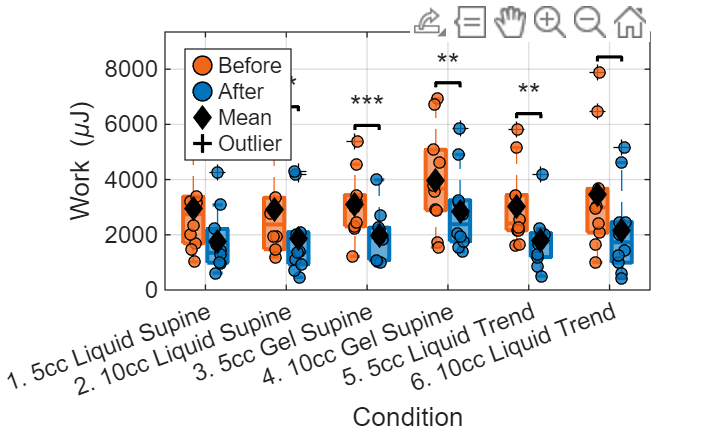



%% 4. Plot Work: boxplots (Pre vs Post across patients) + significance

figure('Name','Group Work (Pre vs Post) - Boxplot');
hold on; grid on; box on;

jit      = 0.15;           % Horizontal offset between Pre and Post within each condition
boxWidth = 0.25;           % Width of each box

colPre  = [0.95 0.40 0.10];   % Orange for Pre
colPost = [0.00 0.45 0.74];   % Blue for Post

maxY_work_global = 0;      % Track global maximum y for setting ylim later


for i = 1:nC
    preVals  = preWorkPts_grp{i};
    postVals = postWorkPts_grp{i};

    % ----- Pre box -----
    % ----- Pre box -----
    if ~isempty(preVals)
        boxplot(preVals, ...
            'positions', i - jit, ...
            'widths',   boxWidth, ...
            'colors',   colPre, ...
            'symbol',   'k+', ...
            'Whisker',  1.5);
    
        % === SOLID COLOR FILL ===
        h = findobj(gca,'Tag','Box');        % handles to all boxes so far
        thisBox = h(1);                      % the most recently created one
        patch(get(thisBox,'XData'), get(thisBox,'YData'), colPre, ...
              'FaceAlpha', 0.6, ...         % 可改成1变纯色
              'EdgeColor', colPre, ...
              'HandleVisibility','off');
    
        % === raw points ===
        x_jitter = (i - jit) + (rand(size(preVals))-0.5)*0.09;
        scatter(x_jitter, preVals, 18, colPre, 'filled', ...
            'MarkerFaceAlpha',0.8, 'MarkerEdgeColor','k');
    
        % mean
        mu_pre = mean(preVals);
        plot(i - jit, mu_pre, 'kd', 'MarkerFaceColor','k', ...
             'MarkerSize',6, 'HandleVisibility','off');
    end


    % ----- Post box -----
    % ----- Post box -----
    if ~isempty(postVals)
        boxplot(postVals, ...
            'positions', i + jit, ...
            'widths',   boxWidth, ...
            'colors',   colPost, ...
            'symbol',   'k+', ...
            'Whisker',  1.5);
    
        % === SOLID COLOR FILL ===
        h = findobj(gca,'Tag','Box');
        thisBox = h(1);
        patch(get(thisBox,'XData'), get(thisBox,'YData'), colPost, ...
              'FaceAlpha', 0.6, ...
              'EdgeColor', colPost, ...
              'HandleVisibility','off');
    
        % === raw points ===
        x_jitter = (i + jit) + (rand(size(postVals))-0.5)*0.09;
        scatter(x_jitter, postVals, 18, colPost, 'filled', ...
            'MarkerFaceAlpha',0.8, 'MarkerEdgeColor','k');
    
        % mean
        mu_post = mean(postVals);
        plot(i + jit, mu_post, 'kd', 'MarkerFaceColor','k', ...
             'MarkerSize',6, 'HandleVisibility','off');
    end

end
% Thicken box, median and whisker lines for better visibility
set(findobj(gca,'Tag','Box'),                 'LineWidth',1.5);
set(findobj(gca,'Tag','Median'),              'LineWidth',1.5);
set(findobj(gca,'Tag','Whisker'),             'LineWidth',1.2);
set(findobj(gca,'Tag','Upper Adjacent Value'),'LineWidth',1.2);
set(findobj(gca,'Tag','Lower Adjacent Value'),'LineWidth',1.2);

% X-axis labelling
xlim([0.5, nC+0.5]);
set(gca,'XTick',1:nC,'XTickLabel',conds,'XTickLabelRotation',20);
ylabel('Work (\muJ)');
xlabel('Condition');
% title('Work by Condition (Across Patients): Pre vs Post (Boxplot)');

% Legend using dummy objects (only Pre / Post)
hPre  = plot(nan,nan,'o', ...
             'MarkerFaceColor', colPre, ...   % 填 Pre 的颜色
             'MarkerEdgeColor', 'k', ...      % 黑色边框
             'LineWidth', 0.6, ...
             'MarkerSize', 8);
hPost = plot(nan,nan,'o', ...
             'MarkerFaceColor', colPost, ...  % 填 Post 的颜色
             'MarkerEdgeColor', 'k', ...      % 黑色边框
             'LineWidth', 0.6, ...
             'MarkerSize', 8);
hMean = plot(nan,nan,'kd','MarkerFaceColor','k','MarkerSize',6);
hOut  = plot(nan,nan,'k+','MarkerSize',8,'LineWidth',1.2);
legend([hPre, hPost, hMean, hOut], ...
       {'Before', 'After', 'Mean', 'Outlier'}, ...
       'Location','northwest');

% ---- Significance brackets using paired t-test p-values (pWork) ----
ylimCurr = ylim;
margin   = 0.05*(ylimCurr(2)-ylimCurr(1));   % Vertical spacing above boxes

for i = 1:nC
    preVals  = preWorkPts_grp{i};
    postVals = postWorkPts_grp{i};

    if isempty(preVals) || isempty(postVals)
        continue;
    end

    % Highest data point for this condition
    localMax = max([preVals(:); postVals(:)]);
    yLine    = localMax + margin;        % height of bracket line
    yStar    = yLine  + 0.6*margin;      % height of asterisk text

    % track for global ylim
    maxY_work_global = max(maxY_work_global, yStar);

    % Draw bracket only if p < 0.05
    if ~isnan(pWork(i)) && pWork(i) < 0.05
        x1 = i - jit;
        x2 = i + jit;

        % horizontal bracket (HandleVisibility off so it won't enter legend)
        plot([x1 x1 x2 x2], ...
             [yLine yLine+0.4*margin yLine+0.4*margin yLine], ...
             'k','LineWidth',1.2, 'HandleVisibility','off');

        % p-value to stars
        if     pWork(i) < 0.001
            stars = '***';
        elseif pWork(i) < 0.01
            stars = '**';
        else
            stars = '*';
        end

        % place stars above bracket
        text((x1+x2)/2, yStar, stars, ...
            'HorizontalAlignment','center', ...
            'VerticalAlignment','bottom', ...
            'FontSize',11);
    end
end

% Final ylim so brackets and stars are visible
if maxY_work_global > 0
    ylim([0, maxY_work_global + 2*margin]);
end

hold off;